# EE 146: Computer Vision

# Buddy Ugwumba SID: 862063029

# Lab 3: Morphological Operators, Connected Component Labeling & region properties 

# Date: 01/19/2022

**Problem 1**

1) Use Matlab built in image 'circles.png.'

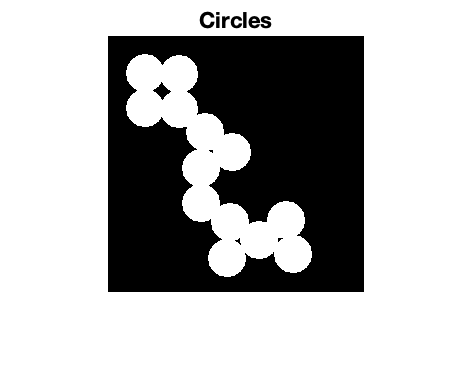

circles_binary = imread('circles.png');
imshow(circles_binary), title('Circles')

2) Using various structuring elements (of various shapes and sizes) perform morphological operations 

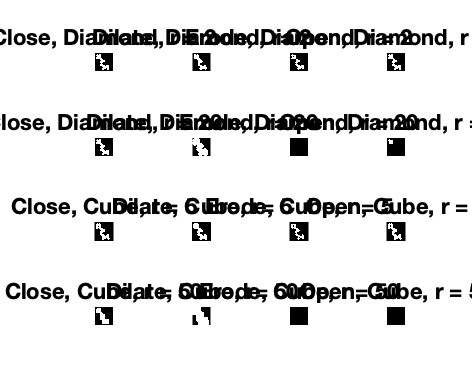

% shape and size is our choice. At least use two shapes and two sizes for
% each operation
% use the Matlab functions and plot in a subplot(4,4,1)
% Create structuring elements
SE_1 =  strel('diamond', 2);
SE_2 = strel('diamond', 20);
SE_3 = strel('cube', 5);
SE_4 = strel('cube', 50);
subplot(4,4,1), imshow(imclose(circles_binary, SE_1)), title('Close, Diamond, r = 2');
subplot(4,4,2), imshow(imdilate(circles_binary, SE_1)), title('Dilate, Diamond, r= 2');
subplot(4,4,3), imshow(imerode(circles_binary, SE_1)), title('Erode, Diamond, r = 2');
subplot(4,4,4), imshow(imopen(circles_binary, SE_1)), title('Open, Diamond, r = 2');
subplot(4,4,5), imshow(imclose(circles_binary, SE_2)), title('Close, Diamond, r = 20');
subplot(4,4,6), imshow(imdilate(circles_binary, SE_2)), title('Dilate, Diamond, r= 20');
subplot(4,4,7), imshow(imerode(circles_binary, SE_2)), title('Erode, Diamond, r = 20');
subplot(4,4,8), imshow(imopen(circles_binary, SE_2)), title('Open, Diamond, r = 20');
subplot(4,4,9), imshow(imclose(circles_binary, SE_3)), title('Close, Cube, r = 5');
subplot(4,4,10), imshow(imdilate(circles_binary, SE_3)), title('Dilate, Cube, r= 5');
subplot(4,4,11), imshow(imerode(circles_binary, SE_3)), title('Erode, Cube, r = 5');
subplot(4,4,12), imshow(imopen(circles_binary, SE_3)), title('Open, Cube, r = 5');
subplot(4,4,13), imshow(imclose(circles_binary, SE_4)), title('Close, Cube, r = 50');
subplot(4,4,14), imshow(imdilate(circles_binary, SE_4)), title('Dilate, Cube, r= 50');
subplot(4,4,15), imshow(imerode(circles_binary, SE_4)), title('Erode, Cube, r = 50');
subplot(4,4,16), imshow(imopen(circles_binary, SE_4)), title('Open, Cube, r = 50');

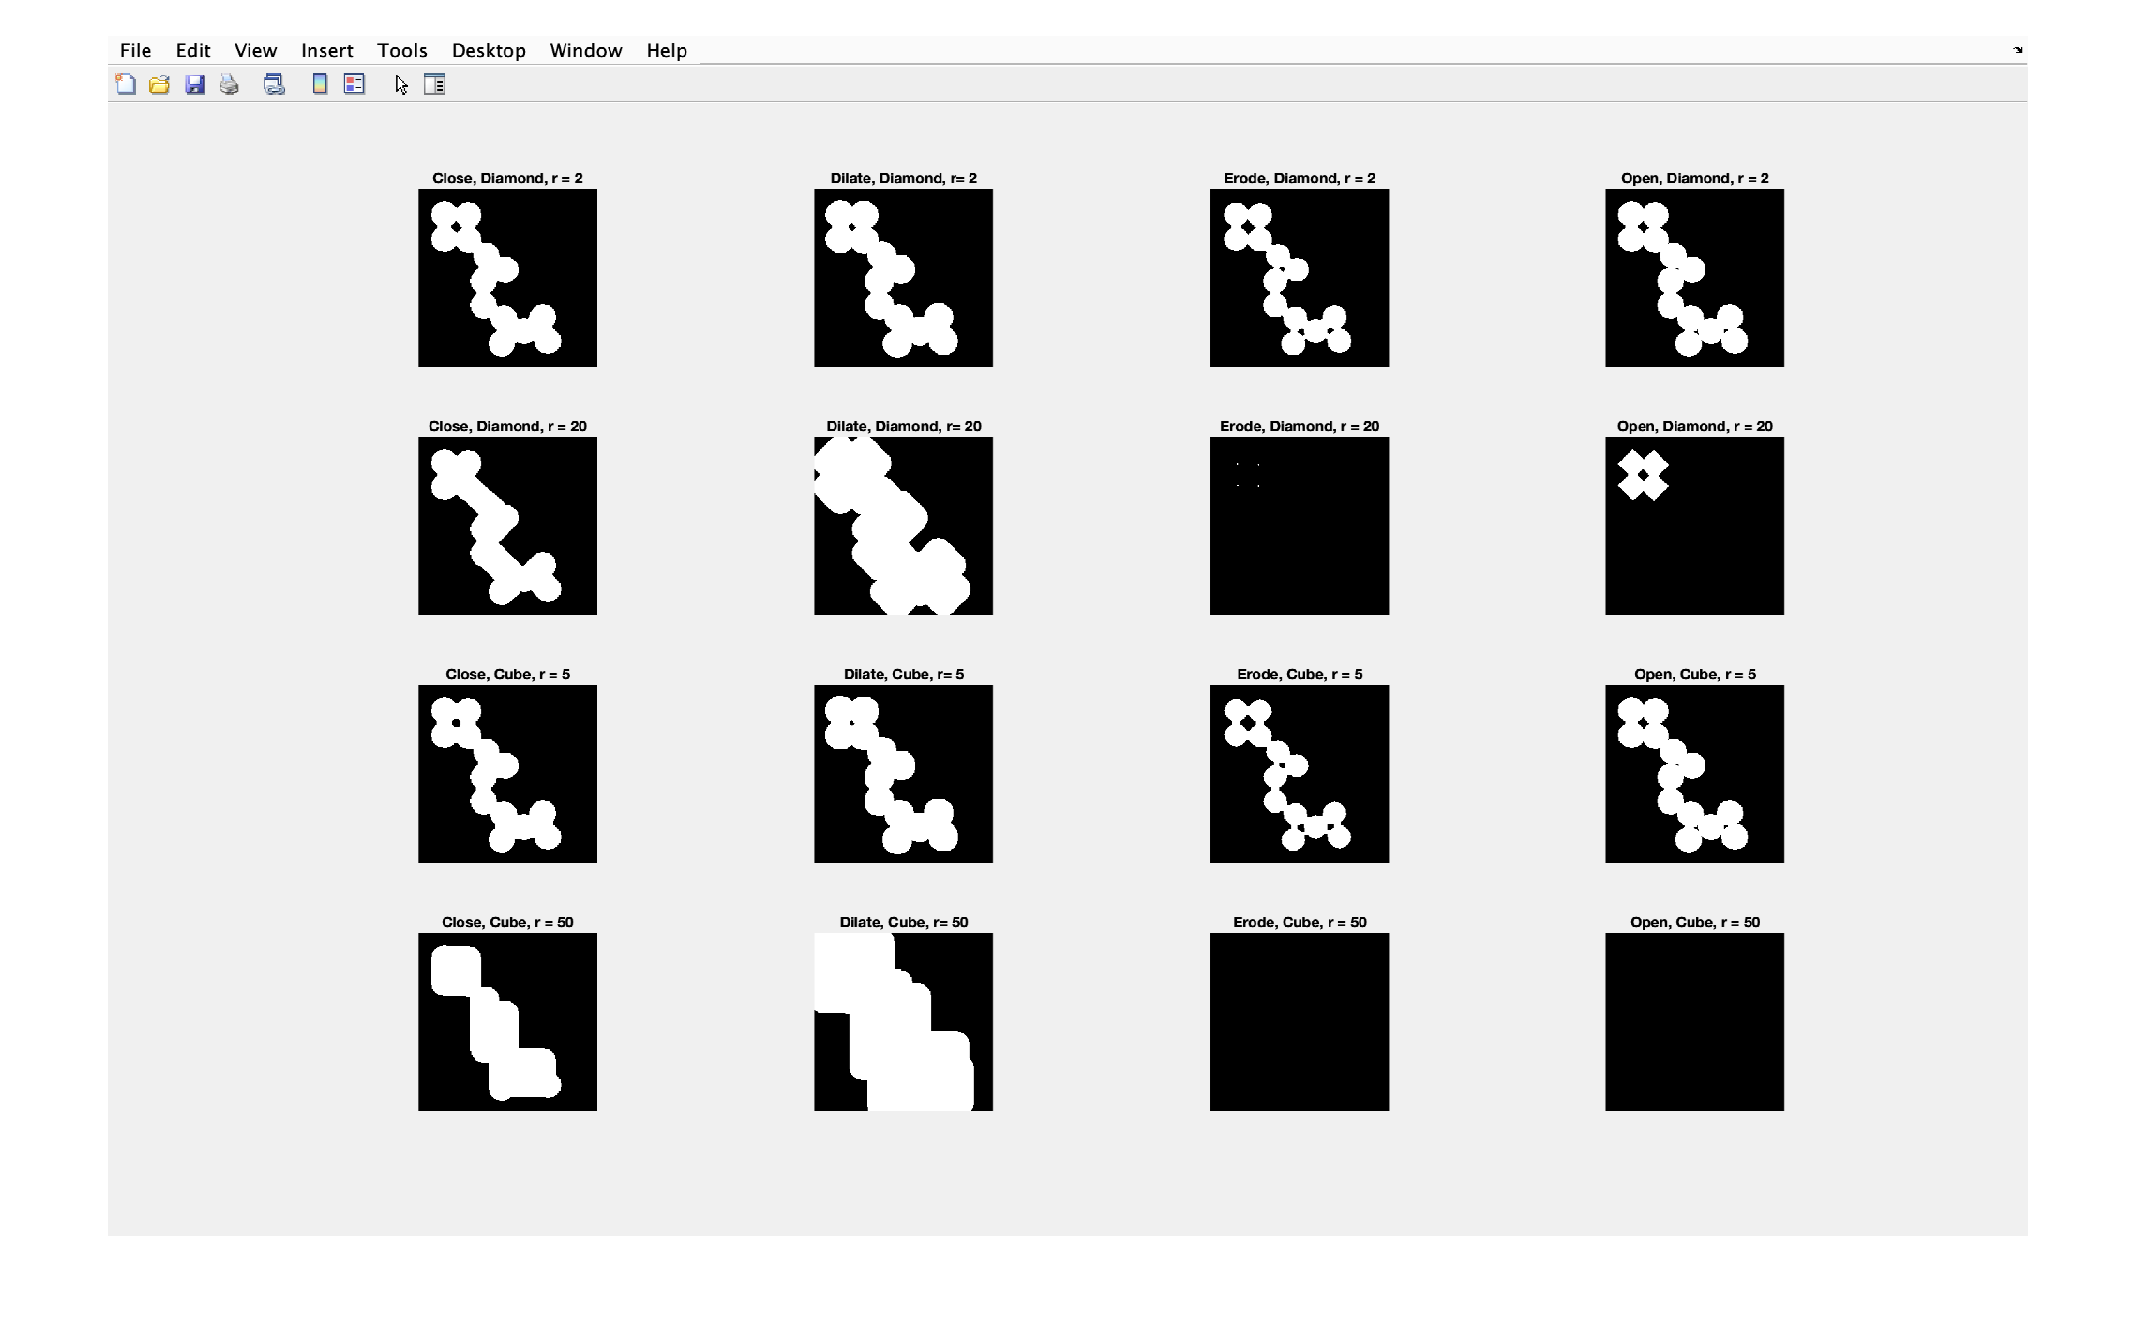

figure
imshow('Problem_1_Results.png')

Problem 2: (Extra Credit if you can implement the first pass, the functions bwlabel and bwconncomp returns only the second pass)

Understand and implement connected componenet labeling algorithm 10.2;

Test my program on two simple data sets


$$I_{\mathrm{m1}} =\left\lbrack \begin{array}{cccccccc}
0 & 0 & 1 & 0 & 0 & 1 & 1 & 1\\
0 & 1 & 1 & 1 & 1 & 1 & 1 & 1\\
1 & 1 & 1 & 1 & 1 & 1 & 1 & 1\\
1 & 1 & 1 & 1 & 1 & 1 & 1 & 1\\
1 & 1 & 1 & 1 & 0 & 0 & 1 & 1\\
1 & 1 & 0 & 0 & 0 & 0 & 0 & 0\\
1 & 1 & 1 & 0 & 0 & 1 & 1 & 1\\
1 & 1 & 1 & 0 & 0 & 1 & 1 & 1
\end{array}\right\rbrack \;I_{\mathrm{m2}} =\left\lbrack \begin{array}{cccccccc}
1 & 1 & 0 & 1 & 1 & 1 & 0 & 1\\
1 & 1 & 0 & 1 & 0 & 1 & 0 & 1\\
1 & 1 & 1 & 1 & 0 & 0 & 0 & 1\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\
1 & 1 & 1 & 1 & 0 & 1 & 0 & 1\\
0 & 0 & 0 & 1 & 0 & 1 & 0 & 1\\
1 & 1 & 0 & 1 & 0 & 0 & 0 & 1\\
1 & 1 & 0 & 1 & 0 & 1 & 1 & 1
\end{array}\right\rbrack \;$$


for the above start label numbering at 2

I_m1 = [0 0 1 0 0 1 1 1;....
    0 1 1 1 1 1 1 1;....
    1 1 1 1 1 1 1 1;....
    1 1 1 1 1 1 1 1;....
    1 1 1 1 0 0 1 1;....
    1 1 0 0 0 0 0 0;....
    1 1 1 0 0 1 1 1;....
    1 1 1 0 0 1 1 1]

I_m1 =      0     0     1     0     0     1     1     1
     0     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1
     1     1     1     1     0     0     1     1
     1     1     0     0     0     0     0     0
     1     1     1     0     0     1     1     1
     1     1     1     0     0     1     1     1


new_Im1 = SequentialLabeling(I_m1)

Neighbors =      2     0     0     3


Neighbors =      2     2     0     3


Neighbors =      2     2     0     3


Neighbors =      3     2     0     3


Neighbors =      3     3     0     3


Neighbors =      3     3     0     4


new_Im1 =      0     0     2     0     0     3     3     3
     0     2     2     2     3     3     3     3
     2     2     2     3     3     3     3     3
     2     2     3     3     3     3     3     3
     2     3     3     3     0     0     3     3
     3     3     0     0     0     0     0     0
     3     3     3     0     0     4     4     4
     3     3     3     0     0     4     4     4


% Compare the results from my algorithm with built in Matlab function to
% check for accuracy
CC_oG_Im1 = bwconncomp(I_m1)

CC_oG_Im1 = struct with fields:
    Connectivity: 8
       ImageSize: [8 8]
      NumObjects: 2
    PixelIdxList: {[41×1 double]  [6×1 double]}


CC_exp_Im1 = bwconncomp(new_Im1)

CC_exp_Im1 = struct with fields:
    Connectivity: 8
       ImageSize: [8 8]
      NumObjects: 2
    PixelIdxList: {[41×1 double]  [6×1 double]}


calcCirculariy(CC_exp_Im1)

props = 2×1 struct array with fields:
    Area
    Centroid
    Perimeter


circularity =     1.4800    0.4035


Final_Question = [ 1 0 1 0 0 1;...
    0 1 1 0 1 1;....
    1 0 0 1 0 0;...
    1 0 1 0 1 1]

Final_Question =      1     0     1     0     0     1
     0     1     1     0     1     1
     1     0     0     1     0     0
     1     0     1     0     1     1


problem_c = SequentialLabeling(Final_Question)

newMatrix =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Index in position 2 is invalid. Array indices must be positive integers or logical values.

Error in Lab_3>SequentialLabeling (line 115)
                    Neighbors(1,4) = newMatrix(u, v-1);


I_m2 = [0 0 1 0 0 1 1 1;....
    1 1 0 1 0 1 0 1;....
    1 1 1 1 0 0 0 1;....
    0 0 0 0 0 0 0 1;....
    1 1 1 1 0 1 0 1;....
    0 0 0 1 0 1 0 1;....
    1 1 0 1 0 0 0 1;....
    1 1 0 1 0 1 1 1]
new_Im2 = SequentialLabeling(I_m2)
% Compare the results from my algorithm with built in Matlab function to
% check for accuracy
CC_oG_Im2 = bwconncomp(I_m2)
CC_exp_Im2 = bwconncomp(new_Im2)
calcCirculariy(CC_exp_Im2)

% Compare the results from my algorithm with built in Matlab function to
% check for accuracy
newCircles_binary = SequentialLabeling(circles_binary);
CC_original = bwconncomp(circles_binary)

CC_original = struct with fields:
    Connectivity: 8
       ImageSize: [256 256]
      NumObjects: 1
    PixelIdxList: {[14134×1 double]}


CC_exp_Og = bwconncomp(newCircles_binary)

CC_exp_Og = struct with fields:
    Connectivity: 8
       ImageSize: [256 256]
      NumObjects: 1
    PixelIdxList: {[14134×1 double]}


As can be seen from the results, the sequential labeling function works								

- Find the connected components in the image and report four properties of components: area, centroid, perimeter, and circularity for each component 						

% Circles original
calcCirculariy(CC_exp_Og)

props = struct with fields:
         Area: 14134
     Centroid: [106.6583 135.0756]
    Perimeter: 952.8480


circularity = 5.1118

% Circles Closed
CC_Closed = bwconncomp(imclose(circles_binary, SE_1));
calcCirculariy(CC_Closed)

props = struct with fields:
         Area: 14262
     Centroid: [106.7082 135.1915]
    Perimeter: 902.2540


circularity = 4.5422

% Circles Dilated
CC_Dilated = bwconncomp(imdilate(circles_binary, SE_1));
calcCirculariy(CC_Dilated)

props = struct with fields:
         Area: 15906
     Centroid: [106.6818 135.1242]
    Perimeter: 912.9560


circularity = 4.1699

% Circles Erosion
CC_Erosion = bwconncomp(imerode(circles_binary, SE_1));
calcCirculariy(CC_Erosion)

props = struct with fields:
         Area: 12261
     Centroid: [106.5234 134.8411]
    Perimeter: 939.3520


circularity = 5.7269

% Circles Open
CC_Open = bwconncomp(imopen(circles_binary, SE_2));
calcCirculariy(CC_Open)

props = struct with fields:
         Area: 3413
     Centroid: [54.5965 55.5904]
    Perimeter: 282.7040


circularity = 1.8635

function newMatrix = SequentialLabeling(binary_image)

% Input should be an integer-valued image with inital values 0 =
% background, and 1 = foreground. Returns nothing but modifies the image

    % Step 1 
    % Assign inital labels
    M = size(binary_image, 1);
    N = size(binary_image, 2);
    % Value of next label to be assigned
    Label = 2;
    % Create an empty list of labels and label collisions
    label_list = {};
    collisions = {};
    % counters for indexing labels
    key1 = 1;
    key2 = 1;
    % Create an array to hold neighbors
    Neighbors = zeros(1,4);
    newMatrix = zeros(size(binary_image,1), size(binary_image,2));
    
    for u = 1:1:M
        newMatrix
        for v = 1:1:N
            % This means that the pixel at this location is a foreground
            % pixel because it has the value 1
            if binary_image(u, v) == 1
                % Check boundary conditions. 
                % Check top boundary condition
                if u == 1
                    Neighbors(1,1) = 0;
                    Neighbors(1,2) = 0;
                    Neighbors(1,3) = 0;
                    Neighbors(1,4) = newMatrix(u, v-1);
                % Check the left boundary condition
                elseif v == 1
                    Neighbors(1,1) = newMatrix(u-1, v+1);
                    Neighbors(1,2) = newMatrix(u-1, v);
                    Neighbors(1,3) = 0
                    Neighbors(1,4) = 0;
                % Check right boundary condition
                elseif v+1 > N
                    Neighbors(1,1) = 0;
                    Neighbors(1,2) = newMatrix(u-1, v);
                    Neighbors(1,3) = newMatrix(u-1, v-1);
                    Neighbors(1,4) = newMatrix(u, v-1);
                % First pass
                else
                    % Using the eight neighbor method
                    Neighbors(1,1) = newMatrix(u-1,v+1);
                    Neighbors(1,2) = newMatrix(u-1, v);
                    Neighbors(1,3) = newMatrix(u-1, v-1);
                    Neighbors(1,4) = newMatrix(u, v-1);
                end
                % Check if all neighbors are 0. If so, change the value of
                % that foreground pixel to the value of the current label,
                % then increment the label by one
                if all(Neighbors(:)==0)
                    newMatrix(u,v) = Label;
                    % Store the label in the label list
                    label_list{key1} = Label;
                    Label = Label + 1;
                    key1 = key1 + 1;
                else
                    neighborCheck = 0;
                    for i = 1:1
                        for j = 1:size(Neighbors,2)
                            if Neighbors(i,j) > 1
                                neighborCheck = neighborCheck + 1;
                            end
                        end
                    end
                    % exactly one neighbor has a value greater than 1
                    if neighborCheck == 1
                        newMatrix(u,v) = max(Neighbors);
                    % if more than one neighbor has a value greater than 1
                    else
                        % Check for duplicate values in Neighbors array so
                        % that we know whether or not to register the
                        % collision
                        c = unique(Neighbors);
                        newMatrix(u,v) = max(Neighbors);
                        if size(c,2) > 2 && c(1,1) ~= 0
                            %Register collisions
                            for i = 1:1
                                for j = 1:size(Neighbors,2)
                                    if Neighbors(i,j) ~= newMatrix(u,v) && Neighbors(i,j) > 1
                                        N_l = Neighbors(i,j);
                                    end
                                end
                            end
                            newMatrix;
                            collisions{key2} = [newMatrix(u,v), N_l];
                            key2 = key2+1;
                        end
                    end
                end
            end
        end
    end
    % The binary image now contains labels 0,2...,label-1
    newMatrix;
    % Resolve collisions
    % Step 2 Resolve Label Collisions
    for i = 1:key2-1
        A = collisions{i}(1,1);
        B = collisions{i}(1,2);
        for j = 1:key1-1
            % Find the sets R(a), R(b) holding labels A, B. a is the index
            % of the set R(a) that contains label A
            if label_list{j} == A
                a = j;
            end
            if label_list{j} == B
                b = j;
            end
        end
        if a ~= b
            label_list{a} = [label_list{a} label_list{b}];
            label_list{b} = [];
        end
    end
    % All equivalent labels (i.e., all labels of pixels in the same
    % connected component) are now contained the same subset of R
    
    % Step 3: Relabel the image
%     for u = 1:M
        for v = 1:N
            if binary_image(u,v) > 1
                for i = 1:size(label_list, 2)
                    if binary_image(u,v) == label_list{i}(1,1) ||...
                            binary_image(u,v) == label_list{i}(1,2)
                        j = i;
                    end
                end
                k = min(label_list{j});
                binary_image(u,v) = k;
            end
        end
    %newMatrix
end

function calcCirculariy(CC_image)

    props = regionprops(CC_image, 'Area', 'Perimeter', "Centroid")
    allAreas = [props.Area];
    allPerimeters = [props.Perimeter];
    circularity = (allPerimeters .^ 2) ./ (4 * pi * allAreas)
    
end